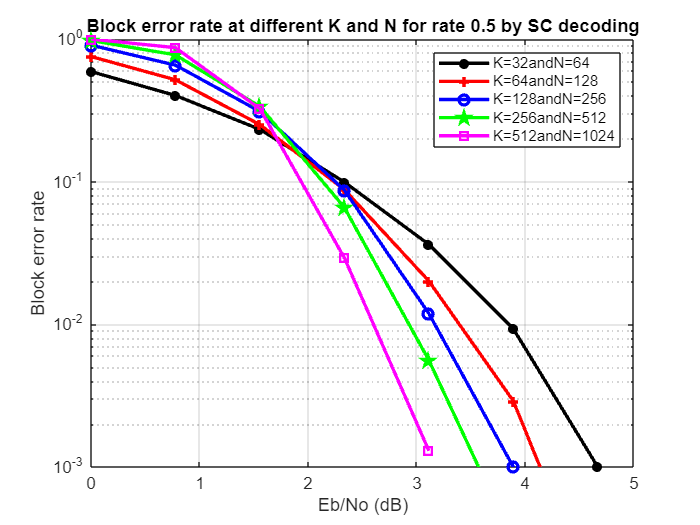

warning('off');
gsck4N16=load("rate0.53264SC.mat");
gsck128N512=load("rate0.564128SC.mat");
gsck4N8=load("rate0.5128256SC.mat");
gsck32N64=load("rate0.5256512SC.mat");
gsck256N512=load("rate0.55121024SC.mat");
figure;
semilogy(gsck4N16.EbNodB,gsck4N16.BLER,'k-*','LineWidth',2,'DisplayName','K=32andN=64');
drawnow;
hold on;
grid on;
semilogy(gsck128N512.EbNodB,gsck128N512.BLER,'r-+','LineWidth',2,'DisplayName','K=64andN=128');
drawnow;
semilogy(gsck4N8.EbNodB,gsck4N8.BLER,'b-o','LineWidth',2,'DisplayName','K=128andN=256');
drawnow;
semilogy(gsck32N64.EbNodB,gsck32N64.BLER,'g-p','LineWidth',2,'DisplayName','K=256andN=512');
drawnow;
semilogy(gsck256N512.EbNodB,gsck256N512.BLER,'m-s','LineWidth',2,'DisplayName','K=512andN=1024');
drawnow;
legend();
xlabel('Eb/No (dB)');
ylabel('Block error rate');
title('Block error rate at different K and N for rate 0.5 by SC decoding');
ylim([1e-03 1e-00]);

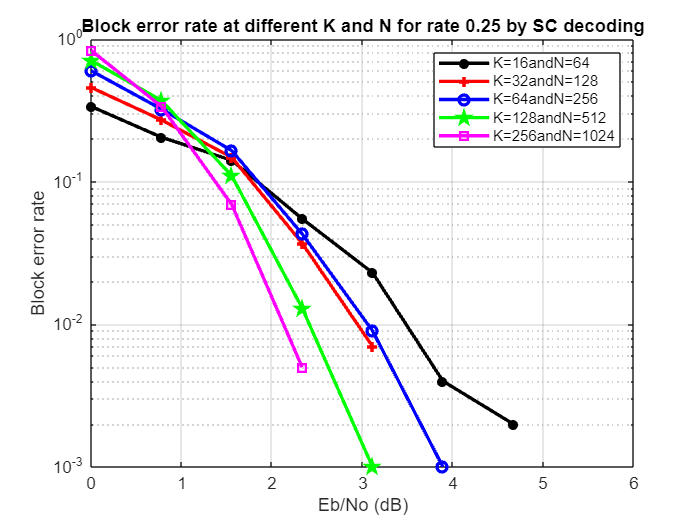


gsck16N64=load("rate0.251664SC.mat");
gsck32N128=load("rate0.2532128SC.mat");
gsck64N256=load("rate0.2564256SC.mat");
gsck128N512=load("rate0.25128512SC.mat");
gsck256N1024=load("rate0.252561024SC.mat");
figure;
semilogy(gsck16N64.EbNodB,gsck16N64.BLER,'k-*','LineWidth',2,'DisplayName','K=16andN=64');
drawnow;
hold on;
grid on;
semilogy(gsck32N128.EbNodB,gsck32N128.BLER,'r-+','LineWidth',2,'DisplayName','K=32andN=128');
drawnow;
semilogy(gsck64N256.EbNodB,gsck64N256.BLER,'b-o','LineWidth',2,'DisplayName','K=64andN=256');
drawnow;
semilogy(gsck128N512.EbNodB,gsck128N512.BLER,'g-p','LineWidth',2,'DisplayName','K=128andN=512');
drawnow;
semilogy(gsck256N1024.EbNodB,gsck256N1024.BLER,'m-s','LineWidth',2,'DisplayName','K=256andN=1024');
drawnow;
legend();
xlabel('Eb/No (dB)');
ylabel('Block error rate');
title('Block error rate at different K and N for rate 0.25 by SC decoding');
ylim([1e-03 1e-00]);

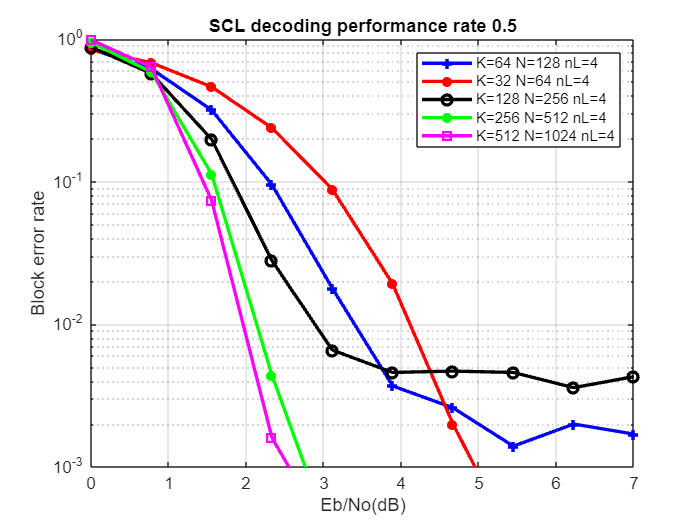

Sclgraph=load("rate0.53264L4.mat");
SCLgraph1=load('rate0.564128L4.mat');
Sclgraph2=load("rate0.5128256L4.mat");
Sclgraph3=load("rate0.5256512L4.mat");
Sclgraph4=load("rate0.55121204L4.mat");
figure;
semilogy(SCLgraph1.EbNodB,SCLgraph1.BLER,'b-+','LineWidth',2,'DisplayName','K=64 N=128 nL=4');
drawnow;
hold on;
semilogy(Sclgraph.EbNodB,Sclgraph.BLER,'r-*','LineWidth',2,'DisplayName','K=32 N=64 nL=4');
drawnow;
grid on;
semilogy(Sclgraph2.EbNodB,Sclgraph2.BLER,'k-o','LineWidth',2,'DisplayName','K=128 N=256 nL=4');
drawnow;
semilogy(Sclgraph3.EbNodB,Sclgraph3.BLER,'g-*','LineWidth',2,'DisplayName','K=256 N=512 nL=4');
drawnow;
semilogy(Sclgraph4.EbNodB,Sclgraph4.BLER,'m-s','LineWidth',2,'DisplayName','K=512 N=1024 nL=4');
drawnow;
hold off;
xlabel('Eb/No(dB)');
ylabel('Block error rate');
legend();
title('SCL decoding performance rate 0.5');
ylim([1e-03 1e-00]);

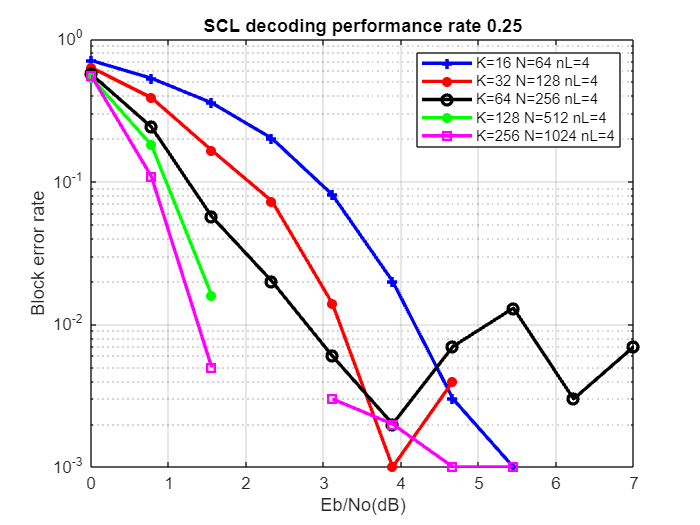


Sclgraph5=load("rate0.251664L4.mat");
SCLgraph6=load('rate0.2532128L4.mat');
Sclgraph7=load("rate0.2564256L4.mat");
Sclgraph8=load("rate0.25128512L4.mat");
Sclgraph9=load("rate0.252561024L4.mat");
figure;
semilogy(Sclgraph5.EbNodB,Sclgraph5.BLER,'b-+','LineWidth',2,'DisplayName','K=16 N=64 nL=4');
drawnow;
hold on;
semilogy(SCLgraph6.EbNodB,SCLgraph6.BLER,'r-*','LineWidth',2,'DisplayName','K=32 N=128 nL=4');
drawnow;
grid on;
semilogy(Sclgraph7.EbNodB,Sclgraph7.BLER,'k-o','LineWidth',2,'DisplayName','K=64 N=256 nL=4');
drawnow;
semilogy(Sclgraph8.EbNodB,Sclgraph8.BLER,'g-*','LineWidth',2,'DisplayName','K=128 N=512 nL=4');
drawnow;
semilogy(Sclgraph9.EbNodB,Sclgraph9.BLER,'m-s','LineWidth',2,'DisplayName','K=256 N=1024 nL=4');
drawnow;
hold off;
xlabel('Eb/No(dB)');
ylabel('Block error rate');
legend();
title('SCL decoding performance rate 0.25');
ylim([1e-03 1e-00]);

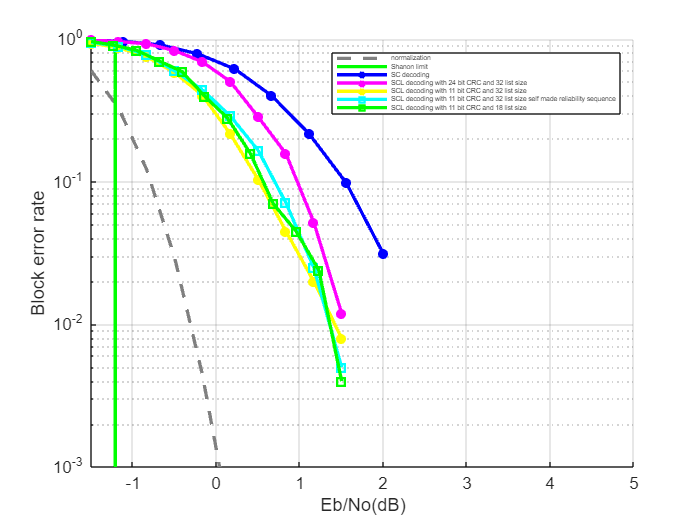

bench=load("SCfinalgraph.mat");
benchscl=load("benchtemp3.mat");
benchscl2=load("benchfinal.mat");
benchsclmyreq=load("benchmyreq1L32.mat");
bl1=load("benchL18notmy.mat");
N=512;
EbNodB=linspace(-1.5,1.5,10);
EbNo=10.^(EbNodB./10);
rate=1/4;
P=rate*EbNo;
C=log2(1+P);
V=(log2(exp(1)))^2*((P.*(P+2))./(2*((P+1)).^2));
Pn=qfunc(sqrt(N./V).*(C-rate+(log2(N)/(2*N))));
s=(2^rate - 1)/rate;
sl=10*log10(s);
figure;
hold on;
grid on;
shaval=linspace(1e-03,1e-00,10);
sl=repmat(sl,1,10);
semilogy(EbNodB,Pn,'--','Color',[0.5 0.5 0.5],'LineWidth',2,'DisplayName','normalization');
drawnow;
set(gca, 'YScale', 'log');
ylim([1e-03 1e-00]);
xlim([-1.5 5]);
semilogy(sl,shaval,'g','LineWidth',2,'DisplayName','Shanon limit');
drawnow;
semilogy(bench.EbNodB,bench.BLER,'b-*','LineWidth',2,'DisplayName','SC decoding');
drawnow;
semilogy(benchscl2.EbNodB,benchscl2.BLER,'m-*','LineWidth',2,'DisplayName','SCL decoding with 24 bit CRC and 32 list size');
drawnow;
semilogy(benchscl.EbNodB,benchscl.BLER,'y-*','LineWidth',2,'DisplayName','SCL decoding with 11 bit CRC and 32 list size');
drawnow;
semilogy(benchsclmyreq.EbNodB,benchsclmyreq.BLER,'c-s','LineWidth',2,'DisplayName','SCL decoding with 11 bit CRC and 32 list size self made reliability sequence');
drawnow;
semilogy(bl1.EbNodB,bl1.BLER,'g-s','LineWidth',2,'DisplayName','SCL decoding with 11 bit CRC and 18 list size');
drawnow;
xlabel('Eb/No(dB)');
ylabel('Block error rate');
legend('Location','northeast',FontSize=4);